clear;
close all;

% Reference - README. 

m = otp.lorenz96.presets.Canonical;

% Not on solution manifold
[~, y] = ode45(m.RHS.F, [0 0.5], m.Y0);
y0 = y(end, :).';

disp(y0)

    7.9994
    8.0004
    8.0002
    7.9999
    7.9999
    8.0000
    8.0001
    8.0001
    8.0003
    8.0008
    8.0018
    8.0035
    8.0053
    8.0056
    8.0014
    7.9911
    7.9799
    7.9820
    8.0086
    8.0422
    8.0357
    7.9733
    7.9285
    7.9817
    8.0706
    8.0542
    7.9547
    7.9371
    8.0173
    8.0507
    7.9990
    7.9677
    7.9953
    8.0171
    8.0046
    7.9922
    7.9971
    8.0032
    8.0015
    7.9989



disp(m)

  Canonical with properties:

    DistanceFunction: @(t,y,i,j)otp.lorenz96.distanceFunction(t,y,i,j)
                Name: 'Lorenz '96'
                 RHS: [1×1 otp.RHS]
            TimeSpan: [2×1 double]
                  Y0: [40×1 double]
          Parameters: [1×1 otp.lorenz96.Lorenz96Parameters]
             NumVars: 40



disp(m);

  Canonical with properties:

    DistanceFunction: @(t,y,i,j)otp.lorenz96.distanceFunction(t,y,i,j)
                Name: 'Lorenz '96'
                 RHS: [1×1 otp.RHS]
            TimeSpan: [2×1 double]
                  Y0: [40×1 double]
          Parameters: [1×1 otp.lorenz96.Lorenz96Parameters]
             NumVars: 40



disp(m.Y0);

    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0080
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000
    8.0000



disp(m.Parameters);

  Lorenz96Parameters with properties:

    F: 8



disp(m.RHS);

  RHS with properties:

                               F: @(t,y)otp.lorenz96.fConst(t,y,forcing)
                          Events: []
                    InitialSlope: []
                        Jacobian: @(t,y)otp.lorenz96.jacobian(t,y)
                        JPattern: []
                            Mass: []
                    MassSingular: []
                MStateDependence: []
                       MvPattern: []
                     NonNegative: []
                      Vectorized: 'on'
           JacobianVectorProduct: @(t,y,u)otp.lorenz96.jacobianVectorProduct(t,y,u)
    JacobianAdjointVectorProduct: @(t,y,u)otp.lorenz96.jacobianAdjointVectorProduct(t,y,u)
     PartialDerivativeParameters: []
           PartialDerivativeTime: []
            HessianVectorProduct: @(t,y,u,v)otp.lorenz96.hessianVectorProduct(t,y,u,v)
     HessianAdjointVectorProduct: @(t,y,u,v)otp.lorenz96.hessianAdjointVectorProduct(t,y,u,v)
       

% My attempt at Q1.1
n_states = 40

n_states = 40


% Inital condition of y0 drawn from N(0,16)
x0 = normrnd(0,4,[n_states,1])

x0 =    -4.9067
    3.2697
    8.2206
    4.1081
   -2.1290
    3.7164
   -3.8210
    6.3887
   -7.5160
    1.2458


% Running for 5 time units (0.5) using inital conditions above

[~, x_true] = ode45(m.RHS.F, [0 0.5], x0);
plot3(x_true(:, 1), x_true(:, 2), x_true(:, 3));
disp(x_true(end,:))

  Columns 1 through 15

    2.2686   -0.2632    4.0029    8.3988    3.1034    5.8115    6.3580   -3.7084    1.8940    8.2715    1.9053   -1.9269    2.2822    2.0178   -1.0054

  Columns 16 through 30

   -0.0067    1.1011    5.6995    2.2232    2.8806    5.7629   -0.3050   -2.1549    2.6719   -0.8445   -1.0521    0.2665    7.7622    0.6035    2.6129

  Columns 31 through 40

    1.7476    0.9763    3.2374    3.3973    0.8186    4.8813   -3.8468   -1.7502   -1.3220    4.0259



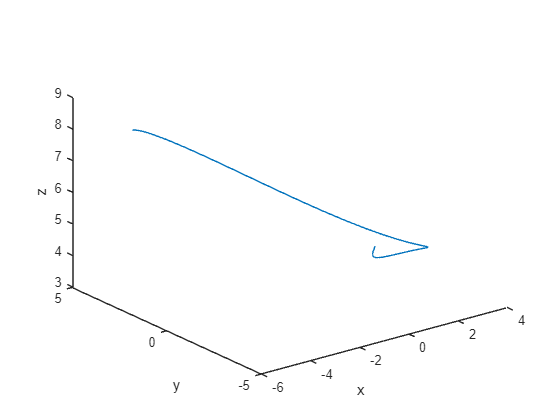

xlabel('x');
ylabel('y');
zlabel('z');

% Propagate for delta_t time units and saving = reference state

x_true = x_true(end,:)

x_true =     2.2686   -0.2632    4.0029    8.3988    3.1034    5.8115    6.3580   -3.7084    1.8940    8.2715    1.9053   -1.9269    2.2822    2.0178   -1.0054   -0.0067    1.1011    5.6995    2.2232    2.8806    5.7629   -0.3050   -2.1549    2.6719   -0.8445   -1.0521    0.2665    7.7622    0.6035    2.6129    1.7476    0.9763    3.2374    3.3973    0.8186    4.8813   -3.8468   -1.7502   -1.3220    4.0259


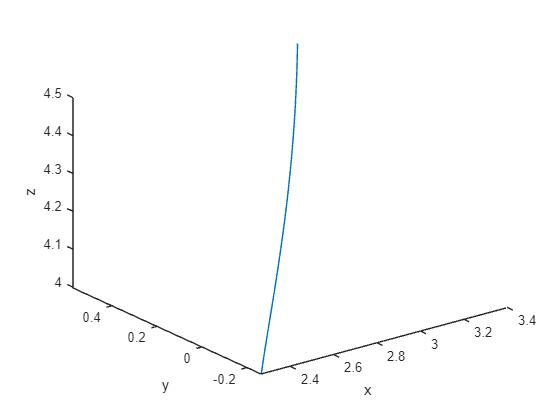


[~, x_true_1] = ode45(m.RHS.F, [0.5 0.6], x_true);
plot3(x_true_1(:, 1), x_true_1(:, 2), x_true_1(:, 3));

xlabel('x');
ylabel('y');
zlabel('z');

% Inital conditions
n_ens = 100

n_ens = 100


sigma = 0.2

sigma = 0.2000


% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens])

eps =     0.1392   -0.0727   -0.1426   -0.2090   -0.0737   -0.0794    0.1217   -0.1284   -0.2402    0.2990    0.1192   -0.0681    0.1047   -0.3873    0.0025   -0.1502    0.2311   -0.0890   -0.2913   -0.0487   -0.1260   -0.0657    0.0356    0.0952    0.2534   -0.0470    0.3065    0.0785    0.1430    0.0093    0.2798   -0.0547    0.1557   -0.0703    0.0209   -0.1399   -0.0848    0.4030   -0.1587    0.1610    0.1780   -0.4280    0.3875   -0.4118   -0.0675   -0.3427   -0.1018    0.0827    0.1891    0.0876
   -0.0831   -0.1013   -0.2522    0.0849   -0.1337   -0.1937    0.1556   -0.2701   -0.0129    0.2128   -0.1037    0.2682   -0.0818   -0.0095    0.0902   -0.0533    0.2027   -0.1714    0.0278   -0.3669    0.0847   -0.1616    0.4068   -0.0722   -0.3339   -0.1366   -0.0224    0.1257    0.2489    0.0053   -0.1744   -0.0524   -0.2129   -0.2040   -0.1938    0.1160   -0.1771   -0.0339   -0.0813    0.1291   -0.1923   -0.1372    0.0195   -0.2214   -0.1068    0.1086   -0.1864    0.3683   -0.0576   

x_perturbed = x_true.' + eps

x_perturbed =     2.4077    2.1958    2.1260    2.0596    2.1949    2.1891    2.3902    2.1402    2.0284    2.5675    2.3877    2.2005    2.3733    1.8812    2.2710    2.1183    2.4996    2.1795    1.9772    2.2198    2.1426    2.2029    2.3042    2.3637    2.5219    2.2215    2.5751    2.3470    2.4116    2.2779    2.5483    2.2138    2.4242    2.1983    2.2895    2.1287    2.1838    2.6716    2.1099    2.4295    2.4466    1.8406    2.6561    1.8568    2.2011    1.9259    2.1668    2.3513    2.4577    2.3562
   -0.3463   -0.3645   -0.5153   -0.1783   -0.3969   -0.4569   -0.1076   -0.5332   -0.2761   -0.0504   -0.3669    0.0050   -0.3450   -0.2727   -0.1730   -0.3165   -0.0605   -0.4346   -0.2354   -0.6301   -0.1785   -0.4248    0.1436   -0.3354   -0.5971   -0.3998   -0.2856   -0.1375   -0.0143   -0.2579   -0.4376   -0.3156   -0.4761   -0.4672   -0.4570   -0.1472   -0.4403   -0.2971   -0.3445   -0.1341   -0.4554   -0.4004   -0.2437   -0.4846   -0.3700   -0.1546   -0.4496    0.1051   -0


% init storage for ensemble (background state)
X = zeros(n_states, n_ens)

X =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% intergate system for one time unit for each ensemble member
for i = 1:n_ens
    [~, x_ens_true] = ode45(m.RHS.F, [0.5 0.6], x_perturbed(:, i));
    X(:, i) = x_ens_true(end,:)
end

X =     3.3552         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059         0         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727         0         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382         0         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255         0         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382    3.1812         0         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255    0.3594         0         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382    3.1812    3.5270         0         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255    0.3594    0.7161         0         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382    3.1812    3.5270    3.3842         0         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255    0.3594    0.7161    0.3721         0         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382    3.1812    3.5270    3.3842    2.8718         0         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255    0.3594    0.7161    0.3721    0.4066         0         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382    3.1812    3.5270    3.3842    2.8718    3.5823         0         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255    0.3594    0.7161    0.3721    0.4066    0.6240         0         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382    3.1812    3.5270    3.3842    2.8718    3.5823    2.8471         0         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255    0.3594    0.7161    0.3721    0.4066    0.6240    0.3283         0         0         0         0         0     

X =     3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789    3.5344    3.1694    3.3188    3.2078    3.2941    3.3686    3.1977    3.6382    3.1812    3.5270    3.3842    2.8718    3.5823    2.8471    3.1095         0         0         0         0         0
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960    0.4165    0.5644    0.4015    0.4005    0.4583    0.7059    0.3727    0.5255    0.3594    0.7161    0.3721    0.4066    0.6240    0.3283    0.3494         0         0         0         0     

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X = 40×100
    3.3552    3.2573    3.2002    3.2306    3.1976    3.2113    3.5676    3.1937    3.1840    3.6755    3.4563    3.3261    3.3558    3.0175    3.3872    3.1618    3.6088    3.3112    3.1201    3.1259    3.2116    3.0528    3.5129    3.4832    3.4377    3.2315    3.5834    3.2720    3.5470    3.1789
    0.4305    0.3965    0.3680    0.7178    0.3179    0.3024    0.7555    0.3331    0.5601    0.9127    0.3871    0.8954    0.4729    0.7081    0.6080    0.4310    0.6545    0.4004    0.5959    0.1898    0.5475    0.3381    1.0367    0.5922    0.3269    0.3843    0.5602    0.6229    0.8101    0.4960
    4.3726    4.2957    4.4758    4.6354    4.0194    4.0948    4.6137    4.2769    4.3729    4.6735    4.2081    4.6809    4.2931    4.9262    4.2375    4.1470    4.4471    4.4051    4.6291    4.3578    4.3053    4.2967    4.8367    4.4920    4.6095    4.3866    4.3193    4.4666    4.5444    4.4259
    9.7131   10.0078   10.1423    9.6805   10.1139    9.8881    9.6413   10.1501    9.

X_covar = cov(X.')

X_covar = 40×40
    0.0414    0.0202    0.0117   -0.0144   -0.0068    0.0088    0.0001   -0.0019   -0.0028    0.0000    0.0022    0.0007    0.0006    0.0029   -0.0031   -0.0042   -0.0000    0.0027    0.0018   -0.0036    0.0015    0.0041    0.0010   -0.0001    0.0032    0.0034    0.0098   -0.0017   -0.0096    0.0033
    0.0202    0.0390    0.0285   -0.0154   -0.0201    0.0035    0.0019   -0.0039   -0.0031    0.0011   -0.0027   -0.0001   -0.0080    0.0026   -0.0011   -0.0058    0.0085   -0.0026   -0.0023    0.0017    0.0049   -0.0032   -0.0014   -0.0019    0.0031   -0.0019    0.0036   -0.0021   -0.0066    0.0020
    0.0117    0.0285    0.0413   -0.0042   -0.0358    0.0050    0.0071   -0.0030    0.0005   -0.0022    0.0001    0.0011   -0.0016    0.0038   -0.0049   -0.0078    0.0050   -0.0006    0.0015    0.0003    0.0078   -0.0010   -0.0021    0.0006    0.0063   -0.0020   -0.0019   -0.0033   -0.0017    0.0009
   -0.0144   -0.0154   -0.0042    0.0400    0.0086   -0.0115    0.0017    0.0073 

% A problem is called well-conditioned, if its condition number is small, i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

cond(X_covar)

ans = 72.3513

% obtain x0b by selecting one state with the smallest deviation from xtrue
[M,I] = min(sum(abs(X - x_true_1(end,:).')))

M = 4.2857

I = 33

x0b = X(:,4)

x0b = 40×1
    3.2306
    0.7178
    4.6354
    9.6805
    4.2874
    4.2632
    2.5288
   -4.0980
    0.7920
    8.9034


x_true_1_final = x_true_1(end,:).'

x_true_1_final = 40×1
    3.3030
    0.5774
    4.4822
    9.8698
    4.4051
    4.1878
    2.5798
   -4.1528
    0.7889
    8.9405


T = 10

T = 10

t = 0.5

t = 0.5000

dt = 0.1

dt = 0.1000

time_steps = 0.5:dt:T

time_steps = 1×96
    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000


X_storage = zeros(n_states, length(time_steps)-1)

X_storage = 40×95
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     


% intergate system for one time unit for each ensemble member
for t_id = 1:(length(time_steps)-1)
    t_start = time_steps(t_id)
    t_end = t_start + dt
    % Runs trajectory and saves at each time step
    [~, x_ens_true] = ode45(m.RHS.F, [t_start t_end], x_true_1_final);
    X_storage(:, t_id) = x_ens_true(end,:)
    x_true_1_final = x_ens_true(end,:)

end

t_start = 0.5000

t_end = 0.6000

X_storage = 40×95
    3.9607         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419         0         0         0         0         0         0         

x_true_1_final = 1×40
    3.9607    1.5239    5.5000   10.9419    2.4354    1.3957    1.1023   -3.4438   -1.1963    8.7769    0.0782   -0.3349    2.8015    3.4087   -0.2282    1.5265    3.4147    7.1901    4.2028    2.5654    3.3294   -2.2109    0.0686    3.4428    1.1861    0.4872    1.4170    8.1861    3.7627    0.8463


t_start = 0.6000

t_end = 0.7000

X_storage = 40×95
    3.9607    3.9441         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505         0         0         0         0         0         

x_true_1_final = 1×40
    3.9441    2.6885    7.0167    9.4505   -2.0062    1.8062    1.3923   -2.7207   -2.4156    7.9382    2.2464   -0.0859    3.2640    3.8703    0.1431    2.1442    5.2026    8.0010    2.8518    1.4245    2.6890   -1.6830    0.6757    4.0131    1.9496    0.9403    2.5150    8.6564    2.7649   -0.2665


t_start = 0.7000

t_end = 0.8000

X_storage = 40×95
    3.9607    3.9441    3.3204         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023         0         0         0         0         

x_true_1_final = 1×40
    3.3204    4.0116    8.1537    4.3023   -4.2508    4.0188    2.2975   -2.6877   -2.7777    6.4132    4.4262   -0.4907    3.7000    4.4652    0.4840    2.7681    7.2212    7.2535   -0.3488    1.3954    2.8854   -0.8478    1.1820    4.7072    2.6143    1.3470    3.7395    8.6994    0.3187   -0.3101


t_start = 0.8000

t_end = 0.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924         0         0         0         

x_true_1_final = 1×40
    2.3493    5.0996    7.3149   -1.8924   -3.4977    3.7540    3.2354   -3.5026   -2.4893    4.4500    5.8819   -0.4065    4.1276    5.2464    0.8309    3.4699    8.7364    3.5028   -2.8286    2.3420    3.6386   -0.1424    1.7470    5.4902    3.1744    1.7774    4.9305    7.5349   -2.1855    0.8849


t_start = 0.9000

t_end = 1

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218         0         0         

x_true_1_final = 1×40
    1.6508    5.7502    4.2900   -5.4218   -1.3717    2.5324    3.3045   -4.0306   -1.5611    2.7916    6.8228    0.8834    4.4820    5.8731    1.2658    4.2174    8.5536   -1.6907   -2.3022    1.9949    4.7129    0.5481    2.3705    6.3594    3.5977    2.2000    5.7710    4.9981   -3.5758    1.8803


t_start = 1

t_end = 1.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423         0         

x_true_1_final = 1×40
    1.9972    6.2032    0.3572   -5.6423   -0.5359    2.4094    3.0082   -3.8994   -0.3677    2.2782    7.5978    3.0361    4.5698    5.9096    1.8954    4.8036    6.2898   -4.7249    0.5560    1.9102    5.3682    1.7217    3.0896    7.1840    3.7693    2.4374    5.9047    1.8320   -3.8314    1.0670


t_start = 1.1000

t_end = 1.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763         

x_true_1_final = 1×40
    2.2157    6.4002   -3.0410   -3.2763   -1.3794    2.2989    2.8582   -3.3899    0.5544    2.9786    8.5929    4.8702    3.9476    5.3956    2.7751    4.8643    3.0278   -5.0226    2.0966    4.0925    5.7971    2.6511    3.9658    7.7117    3.3764    2.3420    5.3673   -0.7569   -2.8986   -0.8213


t_start = 1.2000

t_end = 1.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.8521    6.1502   -4.0015    0.5834   -1.2177    2.2375    3.0176   -2.6892    1.0529    4.4452    9.9965    4.7091    2.3748    5.1108    3.9140    3.9520    0.0822   -4.1663    0.9984    6.2052    6.5376    2.6378    4.7837    7.7826    2.2024    2.1382    4.7029   -1.9327   -0.9514   -1.7290


t_start = 1.3000

t_end = 1.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.0026    5.8415   -2.7039    3.3752    0.8616    2.7167    2.9972   -2.0504    1.2109    6.2045   10.8149    1.3330    1.2957    5.5450    4.9213    1.7139   -1.3835   -2.7873   -0.7438    6.4387    8.1137    2.1392    5.1705    7.3396    0.6881    2.2719    4.3159   -1.8804    1.0038   -0.7228


t_start = 1.4000

t_end = 1.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.6089    5.6605   -0.7378    4.4414    3.2823    2.9272    2.3966   -1.5339    1.1382    7.7268    8.9934   -3.2184    2.2369    6.7406    4.3867   -1.0376   -0.7149   -1.5819   -1.3790    5.3337    9.9030    2.0333    5.0342    6.4594   -0.3532    2.7866    4.2706   -1.2679    2.2646    1.6465


t_start = 1.5000

t_end = 1.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.3448    5.7460    0.9864    4.7757    4.8381    2.3308    1.5470   -0.9294    1.0584    8.5846    4.3232   -5.8158    2.2076    8.7136    1.4445   -2.3767    0.8240   -0.6420   -0.9925    4.2006   11.3055    2.6009    4.2674    5.3580   -0.4831    3.3541    4.5093   -0.5699    2.9418    4.2955


t_start = 1.6000

t_end = 1.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.1863    6.1274    2.2850    4.9509    5.1627    1.1371    1.2175   -0.1571    1.3353    8.7356   -1.2376   -5.4571   -1.5570    9.0209   -0.1764   -1.5869    1.6020    0.3601   -0.1792    3.8828   12.2518    2.6612    2.8141    4.6208    0.3275    3.8064    4.8074    0.0658    3.4150    6.3041


t_start = 1.7000

t_end = 1.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    5.3645    6.4254    2.9367    4.8628    4.4434    0.1375    1.5982    0.7722    2.1633    8.0701   -4.3988   -0.5301   -4.1715    7.6609    2.2259   -1.1668    2.2067    1.3697    0.7865    4.5991   12.4682    0.8621    1.8847    4.7383    1.8512    4.2293    4.8430    0.6557    3.9227    7.0524


t_start = 1.8000

t_end = 1.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    6.6724    5.7378    2.6219    4.5448    3.4736   -0.1642    2.2201    1.9861    3.4041    6.5841   -3.6169    4.3985   -0.5507    7.3289    3.7078   -1.7757    2.9328    2.7022    2.0117    6.1915   10.9842   -2.0211    2.7945    5.7789    3.4979    4.4391    4.4119    1.2808    4.5031    6.2600


t_start = 1.9000

t_end = 2

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    6.2163    3.1947    2.1585    4.5440    2.8691    0.0162    2.7768    3.5537    4.6255    4.6224   -1.8551    5.6689    5.1900    6.6281    1.1657   -1.9031    3.2378    4.6760    3.9595    7.7468    6.5291   -4.1381    3.7866    8.4009    4.3514    3.6467    3.8272    2.1563    5.0137    4.1238


t_start = 2

t_end = 2.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.9978    0.6918    2.6848    5.0861    2.3601    0.3427    3.3111    5.3630    5.0771    2.2575   -0.6922    5.5024    8.6609    2.3149   -2.0377   -0.9477    2.8434    6.9594    6.7433    6.1701   -0.2082   -4.2692    1.3480   10.7737    4.4950    1.5288    3.8054    3.5808    4.9740    1.2146


t_start = 2.1000

t_end = 2.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093         0         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.8772    1.8279    3.8093    5.6471    1.5399    0.7335    3.9804    7.0094    3.7773   -0.0161    0.1992    5.5877    8.3726   -3.1726   -0.5211   -0.5721    2.6573    9.1350    6.8844   -0.6827   -2.4667   -2.4907   -2.0533   10.0845    5.6228   -1.0208    4.1781    5.5648    3.3973   -1.3804


t_start = 2.2000

t_end = 2.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069         0         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354         0         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910         0         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -4.6069    3.8354    6.8910    4.7062    0.0217    1.3286    5.0133    7.6037    0.5969   -0.7495    0.7213    6.1771    5.5367   -5.1478    3.1646    1.3276    3.2452   10.1355    1.2776   -4.5018    0.2865   -1.4787   -3.0004    7.8074    6.4204   -2.8388    4.4423    7.3667   -0.0483   -1.8777


t_start = 2.3000

t_end = 2.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205         0         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410         0         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099         0         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -4.9205    3.0410    9.8099    1.3901   -1.2233    1.7270    6.4759    6.0984   -2.6442    0.6953    1.3522    6.6844    2.0623   -4.8408    3.8725    5.3746    5.3020    7.5828   -4.8749   -1.7318    0.8093   -0.5392   -2.5320    5.8241    6.3844   -3.2187    4.3762    7.9890   -3.1925    0.5232


t_start = 2.4000

t_end = 2.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820         0         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771         0         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910         0         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -4.3820   -0.2771   10.3910   -0.3419   -0.4568    1.7148    7.5009    2.7620   -4.0077    2.0588    3.4870    6.4300   -1.5979   -3.6319    1.4675    8.4030    6.2417    0.0256   -6.0724    0.7840    1.5039    0.0615   -1.6182    4.7470    6.0903   -2.6861    4.2533    7.7146   -3.6631    3.8463


t_start = 2.5000

t_end = 2.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628         0         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435         0         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298         0         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.9628   -3.2435    9.3298    2.1566   -0.1443    2.2193    7.7123   -0.9539   -3.3030    1.2697    5.5439    4.3336   -4.3688   -0.9315   -0.4982    8.6234    3.4075   -5.7471   -3.1818   -0.8074    2.2007    0.6086   -0.6308    4.4520    5.7775   -1.8361    4.2599    7.4646   -2.0591    5.6997


t_start = 2.6000

t_end = 2.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629         0         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835         0         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093         0         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -1.8629   -3.7835    7.0093    5.0626   -1.3895    2.5405    7.3653   -3.3439   -0.6697    0.3260    6.1314    1.6414   -4.7831    1.2761    0.7671    8.4869   -1.0609   -5.6808   -0.6968   -1.3282    2.4306    1.5663    0.4195    4.7326    5.4219   -1.0334    4.3597    7.7051    0.1342    6.2060


t_start = 2.7000

t_end = 2.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924         0         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696         0         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258         0         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.3924   -2.7696    4.9258    6.1622   -2.2220    2.8133    7.0018   -3.4715    2.2870    1.9098    6.1943   -0.8555   -3.7390    1.2760    3.1632    7.4798   -4.8183   -1.8189   -0.5153   -0.7693    2.6969    2.6884    1.6411    5.3211    4.8315   -0.4599    4.5114    8.5563    2.2377    6.0946


t_start = 2.8000

t_end = 2.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842         0         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659         0         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277         0         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    0.9842   -1.8659    3.9277    6.3674   -2.0552    3.1746    6.8996   -2.2516    3.8125    5.0275    4.4880   -3.3040   -1.6574    0.3992    4.3503    5.2041   -5.6899    2.4913    0.6032    0.0022    3.0729    3.9503    3.1056    5.7762    3.7368   -0.0541    4.7344    9.9703    3.7249    5.1209


t_start = 2.9000

t_end = 3.0000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386         0         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773         0         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408         0         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.8386   -1.4773    3.5408    6.4966   -1.3045    3.5454    7.0735   -0.7733    4.3483    6.8262    0.1748   -3.7991   -0.0176    0.5941    4.8669    2.9719   -4.8111    4.1369    3.2353    0.7013    3.6372    5.4558    4.5876    5.3100    2.1633    0.4985    5.2071   11.4413    3.3038    3.1662


t_start = 3

t_end = 3.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163         0         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401         0         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648         0         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.4163   -1.3401    3.3648    6.8394   -0.2314    3.9253    7.4193    0.6084    4.6870    6.0875   -3.7238   -1.4467    0.0437    1.3464    5.3249    0.8904   -3.7864    3.4680    5.6766    1.4225    4.2239    7.1903    5.1453    3.2387    1.0077    1.3724    6.3796   11.6029    0.1681    2.2903


t_start = 3.1000

t_end = 3.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837         0         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071         0         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639         0         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.2837   -1.3071    3.2639    7.4988    1.1125    4.3290    7.7853    1.7452    4.6658    3.6893   -4.8365    1.3979    0.9054    2.1343    5.4907   -1.0003   -2.6125    1.8882    7.2769    3.2353    4.8468    8.2288    3.4210    0.7754    1.1525    2.5141    8.2258    8.6237   -3.4709    3.5507


t_start = 3.2000

t_end = 3.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151         0         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742         0         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961         0         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.2151   -1.2742    3.1961    8.5331    2.7446    4.6434    7.8622    2.2114    3.9103    1.3592   -4.1817    2.2752    2.9809    3.2510    4.7601   -2.3721   -0.9353    0.8741    8.1275    6.5017    5.0812    6.7610    0.3851    0.3146    1.8370    4.2706    9.3544    1.8086   -5.0741    2.7550


t_start = 3.3000

t_end = 3.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135         0
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136         0
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928         0
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.6135   -1.2136    3.0928    9.9475    4.5052    4.3683    7.1984    1.8974    2.9170    0.1319   -3.1084    1.6762    4.9055    4.3474    2.6003   -2.8061    0.6052    1.4742    8.9284    9.1569    2.6550    3.5910   -0.6492    1.1123    2.8302    6.3007    6.8811   -5.2200   -2.1752   -1.2358


t_start = 3.4000

t_end = 3.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.2713   -1.2616    2.8301   11.5640    5.4958    2.6675    6.1236    1.7892    2.2681   -0.1822   -2.0413    0.9168    6.0636    4.5730   -0.4201   -2.1552    1.0342    3.1710   10.4918    7.0407   -2.0476    3.7048    0.5716    1.7750    4.3047    7.1605    0.4153   -6.5421    1.7070   -0.0648


t_start = 3.5000

t_end = 3.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.0100   -1.4444    2.2184   12.7982    4.3035    0.1141    5.8838    2.7133    1.5601   -0.0901   -1.0671    0.6374    6.6413    3.4187   -2.6806   -0.7039    0.9540    4.7839   11.1265   -0.4040   -3.3275    4.4673    3.4681    2.4980    5.5013    4.8815   -5.1077   -3.8977    0.3372    2.4929


t_start = 3.6000

t_end = 3.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    0.8248   -1.2912    1.2671   13.0923    1.6509   -1.1234    6.0131    4.1384    0.2392    0.3213   -0.2005    0.9396    6.9781    1.3471   -3.2504    0.4665    1.6151    6.2136    8.0321   -6.6239   -0.0524    3.4704    5.7382    3.7720    5.0566    0.4977   -5.9532   -1.0431   -0.7669    2.5483


t_start = 3.7000

t_end = 3.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -1.1098   -0.3449    0.8437   12.7511   -0.1469   -0.6700    5.8380    4.7593   -1.2572    1.2740    0.7328    1.7557    7.0504   -0.8364   -2.3122    0.6597    2.8058    7.2292    1.6189   -7.9423    1.1035    5.3674    7.1592    3.8320    2.3909   -2.1683   -4.2184   -0.3992   -0.3629    2.4470


t_start = 3.8000

t_end = 3.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.8982    0.4485    1.6669   12.2121   -0.8901    0.5120    5.9979    4.1383   -2.1071    2.4237    2.1775    2.9903    6.4120   -2.4091   -0.3358    0.7445    3.8176    6.4806   -4.6071   -4.9316   -2.8148    4.5394    8.9268    0.9782    0.5382   -1.9469   -2.7237   -0.2862    0.2264    2.9081


t_start = 3.9000

t_end = 4

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.0493    1.2584    3.1297   11.3644   -1.3792    1.8146    6.6797    2.4449   -2.2725    2.9806    4.3026    4.2676    4.4393   -2.9892    1.5846    1.9343    4.6977    3.6701   -6.5124    1.2310   -3.3163    1.0879    9.7805   -0.0432    1.1102   -1.1495   -1.5789    0.0766    0.9025    3.8327


t_start = 4

t_end = 4.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.1924    3.3641    5.3913    9.3968   -2.2512    2.9599    7.4754   -0.0744   -1.7590    2.6372    6.4652    4.5573    1.1677   -2.6348    2.1745    4.0047    4.8642   -0.1451   -5.5163    4.0501   -0.3359    0.4674    9.7501    1.3731    1.1290   -0.4809   -0.5957    0.6180    1.7565    5.0015


t_start = 4.1000

t_end = 4.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.2837    5.7442    7.8877    4.3171   -3.5661    3.2020    8.0070   -2.4484   -0.1132    2.3590    7.7464    2.9312   -1.6423   -1.5731    1.6948    5.5812    3.3431   -3.2800   -4.1572    3.0755    2.5534    1.8860    9.6037    1.6447    0.1866    0.2050    0.2273    1.2837    2.8650    5.9583


t_start = 4.2000

t_end = 4.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.1077    6.4741    7.9212   -2.9161   -2.6615    1.2353    8.1768   -2.4754    2.0039    3.9225    7.7989   -0.3592   -1.9041   -0.7027    1.4825    6.2705    0.6838   -4.0553   -3.0062    1.0468    4.3681    4.9182    8.4453   -0.5516    0.3204    0.9500    1.0603    2.1080    4.2110    5.8271


t_start = 4.3000

t_end = 4.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    0.4692    6.6075    4.7195   -6.4667    1.1035    1.0316    8.1261   -0.0208    2.9885    6.2864    5.4214   -3.4894    0.4163   -0.1059    1.7877    6.4066   -1.6430   -2.4209   -2.2225   -0.3004    4.9288    8.0313    4.0744   -3.1066    1.9052    2.0381    1.9209    3.1589    5.4067    3.7506


t_start = 4.4000

t_end = 4.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.9313    6.8700    0.0245   -6.2219    1.6311    4.1998    7.8825    1.1956    3.3908    7.1633    0.9275   -4.0768    2.0891    1.5536    2.6440    5.9354   -2.6478    0.3061   -1.4095   -0.5585    4.7049    8.6790   -2.0962   -2.5554    1.9109    3.7182    2.9611    4.2228    5.4902    0.3590


t_start = 4.5000

t_end = 4.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.0844    6.2394   -4.0359   -3.4593   -1.0731    4.9552    8.2632    0.8317    3.7283    6.4722   -2.9630   -2.3569    1.5384    3.3760    3.9579    4.4926   -2.5224    2.5799   -0.1643   -0.0088    4.7364    6.9294   -5.3939    0.8478    1.8813    4.8787    4.6278    4.6675    3.6187   -2.1142


t_start = 4.6000

t_end = 4.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.0296    4.4186   -5.4033    0.8891   -1.2875    3.8030    9.2233    1.1024    3.8731    4.8446   -4.5772    0.2618    1.4432    4.5313    5.0797    2.0885   -1.9490    3.6928    1.4380    0.8488    5.2113    4.1568   -5.6518    2.8214    4.7404    6.0799    5.4399    3.3514    1.0140   -2.3390


t_start = 4.7000

t_end = 4.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.8072    1.9685   -4.8076    3.1585    1.5688    4.1753    9.6210    1.6691    3.4766    3.0123   -4.3550    1.7402    3.1469    5.6438    4.6064   -0.5216   -1.0979    3.9019    3.1207    1.8703    5.4755    1.0560   -5.0651    1.3714    7.7528    7.5316    2.8341    1.1410    0.3125   -1.4802


t_start = 4.8000

t_end = 4.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    5.1740   -0.5141   -3.6995    2.5995    4.9294    6.4698    8.3700    0.5437    3.0728    1.8922   -3.5011    1.6406    5.3162    6.4258    1.6166   -1.8283   -0.3476    3.9715    4.7394    2.9177    4.6740   -1.6627   -3.5666   -1.5046    7.6584    7.9619   -1.8898    1.5211    0.9215   -0.6171


t_start = 4.9000

t_end = 5

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.9467   -2.4574   -2.0652    1.0144    7.0428    9.0984    3.2063   -1.3396    3.6837    1.6721   -2.7367    0.9619    6.7278    5.5493   -2.1987   -0.6838   -0.1279    4.2015    6.3659    3.1630    2.5989   -2.7094   -1.1277   -2.6171    5.5337    7.4087   -3.7950    3.9709    2.4000   -0.0856


t_start = 5

t_end = 5.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.1898   -3.3438    0.0097    0.6980    7.7924    8.1435   -3.7003   -0.2881    3.9286    1.7676   -2.2466    0.3830    7.2857    3.0967   -4.0236    1.3814    0.9956    4.7484    7.4600    1.6888    0.7949   -2.1375    0.6638   -1.7211    4.1818    6.9774   -2.5738    5.5571    4.3892   -0.4109


t_start = 5.1000

t_end = 5.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.0348   -3.2343    1.4858    2.3283    8.3612    2.7123   -6.6328    1.0972    4.8136    1.2334   -1.8748   -0.0296    7.4228    0.6099   -3.8293    1.8867    3.2842    6.1313    6.5675   -0.8878    1.1143   -1.1043    1.6374   -0.1612    4.0169    6.8793   -0.3436    6.0832    5.0524   -1.3272


t_start = 5.2000

t_end = 5.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.8187   -2.5669    1.8060    4.6789    7.3099   -4.1134   -4.4621   -1.5596    5.1512    1.0868   -1.4531   -0.2779    7.4576   -0.8588   -2.5564    1.0860    5.2039    7.6112    2.5866   -2.3467    2.5932    0.4742    2.2872    1.4967    4.7111    7.0044    1.6509    6.0841    3.9072   -2.0011


t_start = 5.3000

t_end = 5.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.2312   -1.6894    1.5768    6.2267    3.3037   -6.8110    1.0729   -2.2014    4.7156    2.2088   -1.3505   -0.2450    7.5010   -1.0300   -0.8824    0.6555    6.1718    7.1324   -2.5294   -1.3490    2.8603    2.4218    2.7746    3.0396    6.0081    7.0651    2.5575    5.3666    1.9482   -1.9444


t_start = 5.4000

t_end = 5.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.4125   -0.8188    1.5676    6.7138   -1.2358   -5.8136    2.6971    1.3047    4.9835    2.3095   -1.6225   -0.1793    7.5334   -0.1554    0.3796    1.2304    6.8199    4.0565   -5.2829    0.5920    3.2116    3.9056    3.5539    4.5771    7.4866    6.1631    1.8477    4.3987    0.6905   -1.2915


t_start = 5.5000

t_end = 5.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.0814   -0.0809    1.9735    6.4001   -4.3405   -3.0959    0.8388    3.6545    5.2211    0.7359   -1.5149   -0.3222    7.5272    1.2709    0.8172    2.2835    7.0866   -0.3647   -5.1066    0.2916    4.3209    5.5465    4.6889    6.1333    7.8573    3.2194    0.7826    4.2133    0.5283   -0.5056


t_start = 5.6000

t_end = 5.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.8596    0.5550    2.6189    5.4112   -5.1744    0.5619    0.5234    4.3343    5.2221   -1.1371   -0.4755   -0.3008    7.4653    2.7023    0.5996    3.1704    6.3430   -3.8513   -2.1953   -1.3306    4.0575    8.2866    6.3804    6.2354    5.3866    0.0150    1.0544    4.5226    0.8419    0.1936


t_start = 5.7000

t_end = 5.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.5962    1.1584    3.2445    4.0506   -4.4263    2.7464    2.9298    5.0506    3.9563   -2.2403    1.0911    0.7923    7.5450    3.3603    0.1076    3.7225    4.8959   -4.7055    1.6804   -0.5620    3.2938   11.0998    7.3504    2.1842    2.4047   -0.4372    1.6550    5.0454    1.1252    0.7887


t_start = 5.8000

t_end = 5.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.1489    1.6495    3.6121    2.6752   -3.4076    2.8493    5.9512    5.0894    0.9730   -2.1524    1.9011    3.0083    7.8056    2.3613   -0.2180    4.1198    3.5955   -3.9241    3.6968    2.4809    4.4710   12.3656    2.6737   -2.2310    2.9438    0.9624    2.2993    5.5206    1.3253    1.3089


t_start = 5.9000

t_end = 6.0000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.2568    1.7796    3.6647    1.5387   -2.5555    1.9580    7.8499    3.2884   -1.9226   -1.0783    1.7766    5.1500    7.4921   -0.2223    0.1808    4.4772    2.6623   -2.9251    3.7049    6.4574    7.7214    8.2401   -4.9772   -0.4345    3.0016    2.9547    3.3316    5.5606    1.3083    1.8143


t_start = 6

t_end = 6.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.6998    1.5014    3.6199    0.8330   -1.7800    1.0818    8.4645    0.6357   -2.5955   -0.2013    1.9272    6.6619    5.5724   -2.7885    1.1691    5.0736    1.7187   -2.1922    2.6600    9.8726    7.0114   -2.9533   -5.7893   -0.1358    3.8074    4.5996    4.4215    4.8157    1.0345    2.3871


t_start = 6.1000

t_end = 6.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.4118    1.3942    3.7123    0.5430   -1.0247    0.7008    8.5125   -1.0060   -1.3216    0.1091    2.4772    7.5732    1.9023   -3.8609    1.2128    5.9443    0.6236   -1.5855    1.4892   10.7693   -0.7921   -6.4861   -1.9462   -2.5391    2.7939    6.9927    5.0175    2.9056    0.9287    3.0613


t_start = 6.2000

t_end = 6.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.2711    1.8357    3.9306    0.4409   -0.3074    0.8964    8.4266   -1.0802    0.4586    0.7198    3.2740    7.4333   -2.0700   -2.5629   -0.1828    6.3549    0.2951   -0.8375    0.9328   10.2670   -5.1984   -0.9935   -1.2031   -2.3900    0.9986    8.4568    5.0174    0.1141    1.3524    3.9618


t_start = 6.3000

t_end = 6.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.0730    2.5783    4.1726    0.3281    0.3775    1.6045    8.3006   -0.2825    1.6579    1.9035    4.3792    5.7705   -4.1940    0.7114   -0.2292    6.4443    0.9821   -0.3142    1.1243    9.6864   -2.9434    4.3869    0.1266   -1.3747    0.0039    8.6671    4.0413   -2.1863    1.9422    5.3097


t_start = 6.4000

t_end = 6.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.6699    3.6185    4.2081    0.1145    1.0556    2.7628    8.1428    0.3659    2.2200    3.3873    5.2676    2.7210   -4.2547    2.7531    2.5953    6.4540    0.8905   -0.0486    1.6300    9.4855    1.5800    5.2938    0.6459   -0.7716   -0.0333    8.5802    2.1539   -3.2137    1.7118    6.6774


t_start = 6.5000

t_end = 6.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.3719    5.1487    3.6753   -0.2598    1.7130    4.3305    7.7797    0.2546    2.6295    4.9414    4.8828   -0.7623   -3.3102    2.0918    5.5745    5.5912   -0.7293    0.6392    2.4734    9.9188    4.1728    2.6724   -0.0578   -0.0591    0.3916    8.5352    0.0249   -2.8727    0.5107    7.3087


t_start = 6.6000

t_end = 6.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.1684    6.7308    2.4614   -0.6415    2.2055    6.1499    6.7127   -0.6432    3.1465    6.3192    2.4847   -2.9223   -1.7615    0.6751    6.7696    4.0689   -2.2866    1.5314    4.2810   10.4717    2.2398   -0.3167    0.3439    0.7212    1.3862    8.3672   -1.5903   -1.1246   -0.3898    7.3796


t_start = 6.7000

t_end = 6.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.0989    7.5733    1.3950   -0.6821    2.4157    7.7334    4.4435   -1.7685    3.4501    7.0897   -1.0178   -2.4207   -0.7328    0.2896    7.0577    2.4085   -2.9356    1.5466    6.6255    9.1548   -2.6753    0.6109    1.0893    1.5746    2.8093    7.6950   -2.2034    1.2851    0.5152    7.4205


t_start = 6.8000

t_end = 6.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    0.4532    7.8572    1.0717   -0.4429    2.5659    8.5619    1.2162   -2.1402    3.0287    7.0984   -3.1981    0.2505   -0.1537    0.6403    7.2213    0.6698   -2.7574    0.5397    7.8467    5.2246   -5.3389    3.3911    3.1204    2.4275    4.2591    6.2824   -2.1193    3.0180    3.2690    7.0692


t_start = 6.9000

t_end = 7

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    0.1150    7.9717    1.2838   -0.2080    2.8599    8.4872   -1.7183   -0.9525    2.3604    6.8110   -2.7592    2.9415    1.3232    1.5764    7.2036   -0.9262   -1.6043   -0.4734    7.8863    1.3729   -5.3866    2.9712    6.3808    3.4924    4.7090    4.3024   -1.7746    3.5832    6.3529    5.0258


t_start = 7

t_end = 7.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.6198    7.8726    1.9437   -0.1579    3.2474    7.7416   -3.0550    1.2450    3.0464    6.4297   -1.0038    4.2214    3.4035    2.8742    6.4211   -1.9625    0.3701   -0.2172    7.8606   -1.2319   -4.0249    0.0850    7.9038    5.7424    3.1758    2.3235   -1.0489    3.4576    8.0549    1.1202


t_start = 7.1000

t_end = 7.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.1015    7.0559    3.3005   -0.3748    3.5924    6.8490   -2.9062    2.8059    5.3615    5.5863    0.0561    4.6598    5.4409    3.7589    4.4285   -2.1243    2.0623    1.7992    7.5970   -2.8279   -1.0830   -1.5872    7.0096    7.8044   -0.1263    1.7990    0.1394    3.6052    7.9277   -2.4674


t_start = 7.2000

t_end = 7.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.9645    5.3960    5.0213   -0.5488    3.9056    6.2165   -2.2601    3.2794    7.7941    3.8905    0.0082    4.9894    7.2910    3.0878    1.9453   -1.5271    2.6486    4.4153    5.9098   -3.4399    2.2012   -0.0644    6.3214    7.6012   -2.4113    3.2995    2.2095    4.4509    6.2003   -4.0066


t_start = 7.3000

t_end = 7.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.6039    3.6609    6.3832    0.0726    4.2793    5.7425   -1.7460    3.2362    9.2754    1.5054   -0.1144    5.2240    8.3358    0.5943    0.8843   -0.5527    2.7624    6.1709    2.9625   -3.3075    3.6474    3.6979    6.8936    4.7687   -3.0022    4.3892    5.6635    4.8721    2.7189   -3.9640


t_start = 7.4000

t_end = 7.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -1.6909    2.5289    7.3956    1.7596    4.4836    4.9255   -1.4658    3.0553    9.7406   -0.6199    0.5181    5.5999    7.8433   -1.8467    2.1052    0.7723    3.2813    6.6782   -0.2814   -2.5879    2.8560    7.2748    6.2459   -0.4190   -2.5204    3.3768    8.5618    2.7980   -0.9104   -2.9898


t_start = 7.5000

t_end = 7.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.7976    2.1816    8.3337    3.8177    3.8066    3.5538   -1.0979    2.8519    9.6075   -1.5256    1.6350    6.6514    5.7725   -2.9219    3.8101    3.2988    4.2614    5.4658   -2.8168   -0.9293    1.6933    8.7285    2.6808   -4.0081   -1.0645    1.8888    9.2866   -0.1397   -1.4046   -1.8031


t_start = 7.6000

t_end = 7.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.0801    2.4388    9.3509    4.6752    1.7112    2.5866   -0.2492    2.9065    9.2531   -1.2609    2.5394    7.8828    2.3463   -3.1311    3.9338    6.6749    4.4485    2.1077   -3.5180    0.5624    2.2310    8.7157   -1.6690   -3.2578   -0.6492    1.5546    9.1371   -1.3292    0.4071   -0.8686


t_start = 7.7000

t_end = 7.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    0.5351    3.1447   10.1967    2.8798   -0.4100    2.8682    1.2223    3.6464    8.7028   -0.6820    3.1395    8.2273   -1.5043   -2.1759    2.3512    8.7918    2.5673   -1.1320   -2.5534    0.5373    3.4772    7.5678   -4.1919    0.4757   -0.4117    1.5185    8.9675   -0.5701    2.0982    0.0473


t_start = 7.8000

t_end = 7.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.1013    4.2127   10.0357   -0.7900   -0.3480    3.2915    3.3384    5.1190    7.4365   -0.5920    3.6163    7.4493   -3.8602    0.4500    1.8889    9.1302    0.0723   -1.6250   -1.4129    0.2416    4.2047    5.8922   -4.0774    3.7278    1.7597    2.4081    8.7977    0.7194    2.5656    0.8485


t_start = 7.9000

t_end = 8

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.8212    5.4490    8.0320   -3.6639    1.6535    4.2249    5.5931    6.3862    4.5208   -0.9495    3.9735    6.2883   -4.1182    2.6563    4.5630    8.0865   -2.3693    0.3411   -0.5859    0.4723    4.7448    4.4611   -2.9663    4.7393    5.2151    4.2205    7.8700    0.8052    2.4702    1.6621


t_start = 8

t_end = 8.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    2.9337    6.3482    4.2249   -4.7151    2.4840    7.0309    7.6172    4.4985    0.6865   -0.5853    4.0987    5.2984   -3.5627    2.9920    7.7599    4.2211   -4.1013    3.0119    0.9958    1.1933    5.3238    3.2247   -2.0736    4.3203    8.8026    5.7352    4.5657   -0.0198    2.8148    2.8634


t_start = 8.1000

t_end = 8.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.4772    5.8231   -0.3802   -4.2778    0.1993    8.9624    7.6590   -1.4044    0.1062    0.1980    4.3867    4.2903   -3.1588    2.2777    9.0548   -0.9347   -3.6698    3.2272    3.5338    2.3058    5.5872    1.8467   -1.5017    3.3923   11.3299    4.1092   -0.2145    0.2319    3.3209    4.5224


t_start = 8.2000

t_end = 8.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    5.7265    2.7587   -3.1934   -1.9841   -2.2753    7.7822    5.7380   -5.1205    2.7524    2.1479    4.8705    2.8391   -3.0738    1.2080    9.0532   -3.6914   -0.8878    2.1351    5.3340    4.0166    4.7262    0.2666   -0.8295    2.6317   11.9158   -0.2790   -1.4690    0.7013    4.1223    6.2383


t_start = 8.3000

t_end = 8.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    4.9219   -1.4147   -2.5759   -0.1241   -2.1924    6.4995    3.8985   -5.5398    3.5884    6.0646    4.3192    0.1535   -2.6324   -0.2044    8.9219   -2.4012    2.0309    3.3346    6.5182    4.9471    2.2215   -0.7148    0.0226    2.7000   11.1986   -2.6546    1.2354    1.3077    5.0855    7.4786


t_start = 8.4000

t_end = 8.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.5127   -3.3387   -0.8425    0.5302   -1.0494    6.1930    2.0503   -5.2188    1.6738    8.5519    1.8811   -1.9290   -1.2303   -1.2586    8.6979    1.4982    2.8918    5.6342    7.2451    2.7574   -0.1815   -0.2437    0.6732    3.5840   10.0470   -2.0645    3.8271    4.0733    6.3774    6.3979


t_start = 8.5000

t_end = 8.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.1940   -1.9172   -0.3030    1.1275    0.3408    6.3293   -0.0952   -4.4761   -1.3474    8.6353    0.6522   -1.8966    0.0744   -0.9095    8.1762    5.3469    2.7191    6.7525    6.0470   -1.0496    0.0456    0.5431    1.4502    4.9138    8.8509   -0.9513    4.7470    7.8100    6.2473    1.6166


t_start = 8.6000

t_end = 8.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -4.0037    1.0724    0.3681    1.7644    1.9437    6.1683   -2.1126   -2.2566   -3.5245    7.4205    1.9809   -1.7773    1.0744    0.4889    8.0193    7.7679    2.3481    6.3803    3.2249   -2.8228    1.5004    1.6079    2.5527    6.5177    7.2748   -0.7211    4.9864   10.1114    1.4360   -2.0951


t_start = 8.7000

t_end = 8.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -3.8921    2.4769    2.2834    2.4448    3.3893    5.0908   -2.9561    1.0440   -2.9554    6.3251    3.5302   -2.2453    1.9775    2.7453    8.9756    7.9231    0.9626    5.5399    1.1030   -2.5940    2.0131    3.3119    4.3271    7.7218    4.3684   -1.1307    4.9051    9.5993   -3.9112    0.4708


t_start = 8.8000

t_end = 8.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.4021    1.6939    4.1019    3.5073    4.0572    3.2793   -2.5321    3.2641    0.0764    6.2328    3.4115   -2.6433    2.3898    5.8852   10.4073    3.8366   -0.8424    5.7460    0.6171   -1.8367    1.8515    5.2067    6.8907    6.5047   -0.0049   -0.8546    4.5209    7.8991   -4.4256    4.7579


t_start = 8.9000

t_end = 9

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -1.0334    1.0295    5.1914    5.0878    3.4101    1.3899   -1.5932    3.8232    3.7156    6.0856    1.1071   -2.5611    1.6527    8.6404    8.6179   -3.4524   -0.1628    5.9608    0.8927   -1.2036    1.6775    7.0250    8.1970    0.8590   -2.3100   -0.1941    4.4969    6.6285   -2.3907    6.2417


t_start = 9

t_end = 9.1000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.7447    0.9849    6.0704    6.1084    1.1972    0.4736   -0.5897    3.7957    6.4245    4.0772   -1.8587   -1.3769    0.4081    9.3780    2.6232   -7.1701    0.1964    6.3884    0.8175   -0.6932    1.6658    8.3770    5.2204   -4.6100    0.1209   -0.1669    4.6374    6.3010   -0.3362    6.3601


t_start = 9.1000

t_end = 9.2000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -0.0293    1.3406    6.9328    5.4618   -1.4152    1.2563    0.5402    4.1646    7.3839    0.1381   -2.5117   -0.0691    0.4273    9.2503   -3.0106   -5.1125   -3.1559    5.5282    1.9966   -0.3719    1.9147    8.8214   -0.3489   -5.1757    1.6928    1.8429    5.2871    6.3949    1.4116    6.6163


t_start = 9.2000

t_end = 9.3000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    1.4842    2.3054    7.6133    2.8973   -2.7351    2.4532    2.5335    5.1796    5.9865   -3.2280   -0.4483    0.3742    1.3134    8.7667   -4.4016    1.2867   -3.7369    3.8838    4.1242   -0.2668    2.3209    8.2571   -4.4099   -1.9791    0.4568    3.4649    6.9448    6.0958    2.4658    6.8336


t_start = 9.3000

t_end = 9.4000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    3.4258    3.7945    7.1927   -0.6890   -2.2433    2.3179    5.0337    5.9616    1.9767   -4.1442    1.5340    1.5318    2.5531    7.9656   -1.8189    5.2456   -0.2140    3.9763    5.1892   -0.0589    2.8131    7.0602   -4.9369    2.2692    1.4543    4.3590    8.9035    5.2100    2.3273    6.5757


t_start = 9.4000

t_end = 9.5000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    5.6404    4.9968    4.3498   -3.2197   -0.4991    1.8497    6.6513    4.7273   -2.5113   -2.8572    1.2389    3.1812    4.4287    7.0632    0.7270    5.8205    3.0192    4.2547    4.8620    0.1820    3.3119    5.8974   -3.4740    4.1701    5.2376    6.4532    9.1153    2.5502    1.7715    6.3318


t_start = 9.5000

t_end = 9.6000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    7.5808    3.7752    0.2306   -3.1793    0.3366    2.5077    7.3549    1.1400   -4.1386   -1.0943    0.5887    4.2343    6.7858    5.8212    1.5401    5.7635    5.0936    4.0093    3.6692    0.6605    3.8030    5.0519   -2.0404    4.0632    9.6672    8.4348    3.8882   -0.7222    2.1763    6.5443


t_start = 9.6000

t_end = 9.7000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    7.7870   -0.3026   -0.8751   -2.0437    0.1863    3.2828    7.0706   -2.6414   -2.3153   -0.6638    0.6861    5.0927    8.7465    3.6011    1.2894    6.1144    6.5117    2.7671    2.4972    1.5164    4.3724    4.3080   -1.2232    3.4605   12.5409    3.8929   -3.4690   -0.0609    2.3470    6.8633


t_start = 9.7000

t_end = 9.8000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    5.1357   -3.4054    1.5357   -0.9716    0.4173    3.9206    5.8051   -4.2535    1.0718   -0.0438    1.0984    6.1560    9.2269    0.2385    1.4199    6.8913    6.8876    0.5315    2.2503    2.7809    5.0207    3.2475   -0.8750    3.0338   12.3454   -3.8614   -1.9654   -0.2027    2.9486    6.8911


t_start = 9.8000

t_end = 9.9000

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
    0.9839   -3.6230    3.2269    0.9954    1.1180    4.6402    3.9866   -3.9956    3.3429    2.0482    2.1215    7.4053    7.0935   -3.0211    2.0734    8.3154    5.2032   -1.7158    2.8923    4.7163    5.2214    1.5055   -0.5504    2.8710   10.7735   -4.6055    4.2045    1.6362    3.5034    6.7261


t_start = 9.9000

t_end = 10

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

x_true_1_final = 1×40
   -2.0507   -2.3117    2.9249    3.0562    2.1295    5.0599    1.9391   -3.2073    3.6380    4.9096    4.0379    7.6885    1.9816   -4.5952    0.8842    9.5485    1.9077   -2.8009    2.7799    7.0483    3.9987   -0.6328    0.1693    3.1660    9.7954   -0.7930    6.4113    5.7523    3.9539    5.1687


X_storage

X_storage = 40×95
    3.9607    3.9441    3.3204    2.3493    1.6508    1.9972    2.2157    1.8521    2.0026    2.6089    3.3448    4.1863    5.3645    6.6724    6.2163    1.9978   -2.8772   -4.6069   -4.9205   -4.3820   -2.9628   -1.8629   -0.3924    0.9842    1.8386    2.4163    3.2837    4.2151    4.6135    4.2713
    1.5239    2.6885    4.0116    5.0996    5.7502    6.2032    6.4002    6.1502    5.8415    5.6605    5.7460    6.1274    6.4254    5.7378    3.1947    0.6918    1.8279    3.8354    3.0410   -0.2771   -3.2435   -3.7835   -2.7696   -1.8659   -1.4773   -1.3401   -1.3071   -1.2742   -1.2136   -1.2616
    5.5000    7.0167    8.1537    7.3149    4.2900    0.3572   -3.0410   -4.0015   -2.7039   -0.7378    0.9864    2.2850    2.9367    2.6219    2.1585    2.6848    3.8093    6.8910    9.8099   10.3910    9.3298    7.0093    4.9258    3.9277    3.5408    3.3648    3.2639    3.1961    3.0928    2.8301
   10.9419    9.4505    4.3023   -1.8924   -5.4218   -5.6423   -3.2763    0.583

 A = eye(20)

A =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    

M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2))

H =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    

X_obvs = X_storage.' * H

X_obvs =     3.9607    5.5000    2.4354    1.1023   -1.1963    0.0782    2.8015   -0.2282    3.4147    4.2028    3.3294    0.0686    1.1861    1.4170    3.7627    2.6464    4.6525    2.2116   -2.3286    1.6800
    3.9441    7.0167   -2.0062    1.3923   -2.4156    2.2464    3.2640    0.1431    5.2026    2.8518    2.6890    0.6757    1.9496    2.5150    2.7649    3.1428    5.3339    1.9453   -1.0972    4.1720
    3.3204    8.1537   -4.2508    2.2975   -2.7777    4.4262    3.7000    0.4840    7.2212   -0.3488    2.8854    1.1820    2.6143    3.7395    0.3187    3.4350    5.2437    1.7470    0.1455    6.4203
    2.3493    7.3149   -3.4977    3.2354   -2.4893    5.8819    4.1276    0.8309    8.7364   -2.8286    3.6386    1.7470    3.1744    4.9305   -2.1855    4.1024    3.2945    2.1752    1.4171    8.2638
    1.6508    4.2900   -1.3717    3.3045   -1.5611    6.8228    4.4820    1.2658    8.5536   -2.3022    4.7129    2.3705    3.5977    5.7710   -3.5758    6.1502   -0.7107    2.6570    2.9

noise_obvs = normrnd(0,0.025,size(X_obvs))

noise_obvs =    -0.0026    0.0008   -0.0062    0.0086   -0.0142    0.0007    0.0206   -0.0102    0.0105   -0.0103    0.0337    0.0091   -0.0054   -0.0036   -0.0310   -0.0188    0.0185    0.0201    0.0231   -0.0029
    0.0349   -0.0433   -0.0136   -0.0482   -0.0140    0.0054    0.0000   -0.0256   -0.0002   -0.0139   -0.0178   -0.0199   -0.0012   -0.0188   -0.0057   -0.0073    0.0050   -0.0331   -0.0401    0.0147
    0.0306    0.0090   -0.0345    0.0183    0.0072   -0.0166   -0.0294   -0.0588    0.0033   -0.0113    0.0069   -0.0509    0.0212    0.0298   -0.0204    0.0196   -0.0073   -0.0102    0.0469   -0.0014
   -0.0016    0.0043   -0.0111    0.0220    0.0407   -0.0233   -0.0141    0.0091   -0.0151   -0.0032   -0.0019    0.0053   -0.0281    0.0028   -0.0314    0.0134   -0.0123   -0.0014    0.0054    0.0000
   -0.0170   -0.0271    0.0008    0.0309    0.0129    0.0615   -0.0443   -0.0020    0.0496   -0.0176    0.0353    0.0072   -0.0112    0.0155   -0.0424   -0.0263    0.0266    0.0177   

X_obvs_noise = X_obvs + noise_obvs

X_obvs_noise =     3.9581    5.5008    2.4292    1.1110   -1.2105    0.0789    2.8221   -0.2385    3.4252    4.1925    3.3631    0.0777    1.1807    1.4133    3.7317    2.6276    4.6710    2.2316   -2.3055    1.6771
    3.9790    6.9735   -2.0198    1.3441   -2.4296    2.2518    3.2640    0.1175    5.2024    2.8379    2.6712    0.6558    1.9484    2.4963    2.7592    3.1355    5.3389    1.9122   -1.1374    4.1867
    3.3510    8.1628   -4.2853    2.3158   -2.7705    4.4096    3.6706    0.4252    7.2245   -0.3601    2.8923    1.1312    2.6355    3.7694    0.2984    3.4546    5.2364    1.7369    0.1924    6.4190
    2.3478    7.3192   -3.5088    3.2573   -2.4487    5.8585    4.1135    0.8399    8.7213   -2.8318    3.6366    1.7523    3.1463    4.9333   -2.2170    4.1158    3.2822    2.1738    1.4225    8.2639
    1.6338    4.2629   -1.3709    3.3354   -1.5483    6.8843    4.4377    1.2638    8.6032   -2.3198    4.7482    2.3778    3.5865    5.7866   -3.6182    6.1239   -0.6841    2.6746 

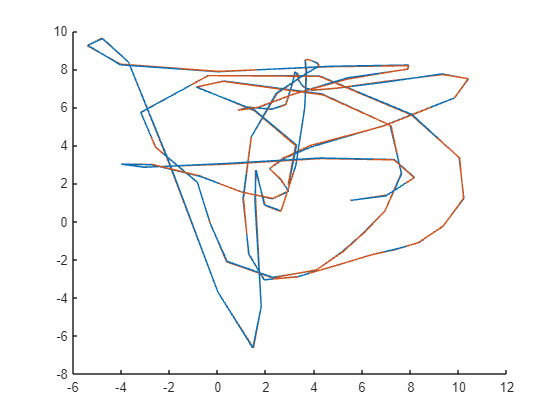

clf
hold on
plot3(X_obvs_noise(:, 2), X_obvs_noise(:, 4), X_obvs_noise(:, 6));
plot3(X_obvs(:, 2), X_obvs(:, 4), X_obvs(:, 6));